# Deep Learning with Point Clouds

After you have exported the labeled data, load the labels into the workspace

load gTruth

If this is the first time you are running this code, be sure to use the code below so that the gTruth knows where the 'parkingLot' folder is saved on your computer. 

firstTime = false;

if firstTime
    oldPath = gTruth.DataSource.SourceName;

ans = 1×3 cell array
    {1×1 pointCloud}    {4×9 double}    {4×1 categorical}



    % Fill this in with the location of the parkingLot folder. 
    newPath = "";

    alternativePaths = {[currentPathPixels newPathPixels]};
    unresolvedPaths = changeFilePaths(gTruth,alternativePaths);

    % Save the updated gTruth

    save gTruth gTruth

    % Repeat for test data
    load gTruthTest
    oldPath = gTruthTest.DataSource.SourceName;

    % Fill this in with the location of the testData folder. 
    newPath = "";


ans = 1×3 cell array
    {1×1 pointCloud}    {10×9 double}    {10×1 categorical}


    alternativePaths = {[currentPathPixels newPathPixels]};
    unresolvedPaths = changeFilePaths(gTruthTest,alternativePaths);

    % save the updated gTruthTest
    save gTruthTest gTruthTest
    clear gTruthTest
end

## Import Labeled Data

Create two datastores to access all the data and associate these labels with the corresponding point clouds.

[pcds,bxds] = lidarObjectDetectorTrainingData(gTruth, "SamplingFactor",1);
dsTrain = combine(pcds, bxds);
preview(dsTrain)

## Augment the Data

Augmentation is a great way to make your dataset, and therefore your object detector, more robust. Use the `sampleLidarData` function to collect point cloud samples from each of the classes present in the data. For example, the image below shows a sample of the 'car' class.

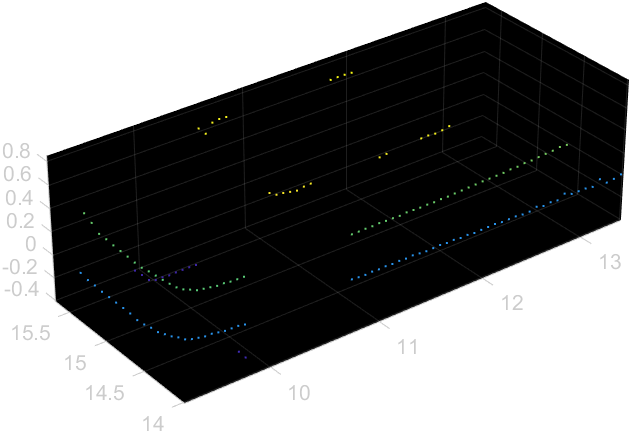

classNames = ["car", "barrel", "cone"]; 
sampleLocation = fullfile(pwd, "parkingLotSampled");
[ldsSampled,bdsSampled] = sampleLidarData(dsTrain,classNames,...
    WriteLocation=sampleLocation,Verbose=false);
dsSampled = combine(ldsSampled,bdsSampled);

Then use the apply the 'pcBboxOversample' function to insert these samples into each point cloud, ensuring that each point cloud will have at least 3 of each object. This artificially creates more data to train the network with. The images below are an example of what this might look like.

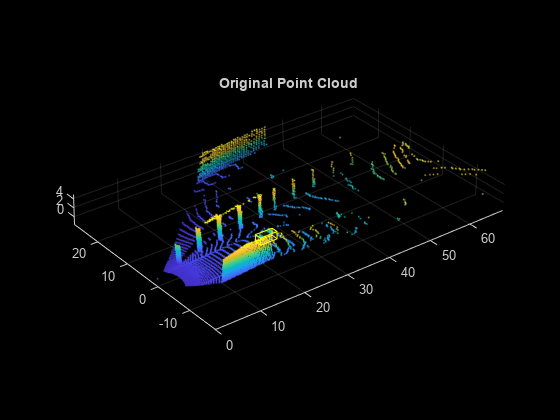 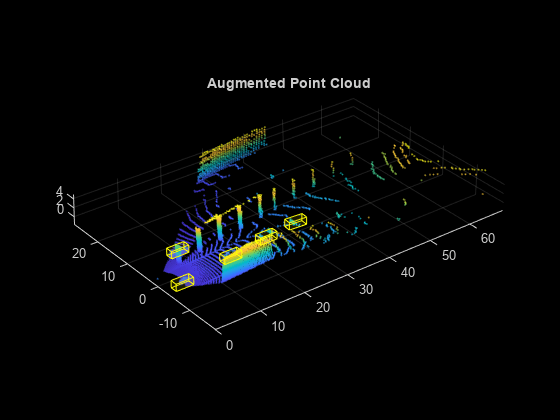

totalObjects = 3;
dsOversampled = transform(dsTrain,...
    @(x)pcBboxOversample(x,dsSampled,classNames,totalObjects));

preview(dsOversampled)

Apply these additional data augmentation techniques to every point cloud, which will add more variety to the training data

- Random rotation along the z axis in the range of [-45, 45] degrees

- Random translation along the x- and y-axis oin the range of [-30, 30] pixels

dsAugmented = transform(dsOversampled,@(x)augmentData(x));

For example, this frame:

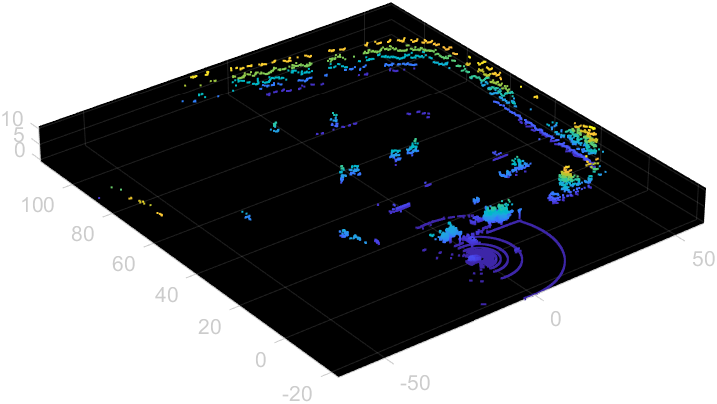

May look more like this:

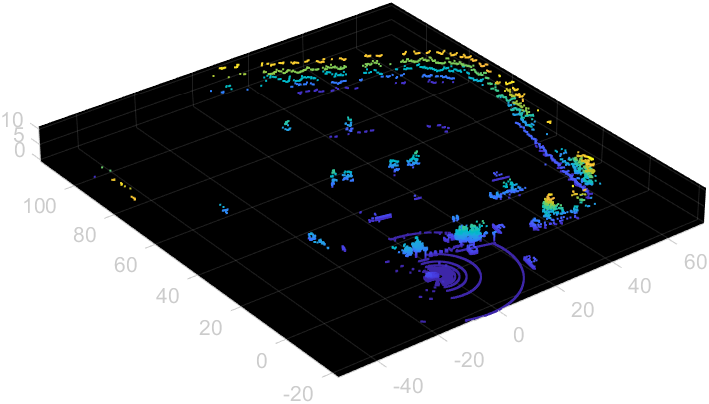

For more ideas on how to augment your data, check out this [documentation page](https://www.mathworks.com/help/lidar/ug/data-augmentations-for-lidar-object-detection-networks.html)!

## Train a PointPillars Network

#### 1. Configure Object Detector

Specify the class names, anchor boxes, point cloud range, and the voxel size. Configure the PointPillars object detector for training and inference.

anchorBoxes = calculateAnchorsPointPillars(gTruth.LabelData);

*************************************************************************
Processing data in minibatchqueue....

*************************************************************************
Data processing complete.

*************************************************************************
Training a PointPillars Object Detector for the following object classes:

* car
* barrel
* cone

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      1         50         00:04:45        0.001         1.8284   
      1         100        00:09:12        0.001         1.0551   
      1         150        00:13:42        0.001        0.81783   
      1         200        00:18:10        0.001        0.76182   
      1         250        00:22:45     

xMin = -5.06;
xMax = 42.26;
yMin = -23; 
yMax = 23;
zMin = -0.52;
zMax = 10.66;

% (xmax-xmin)/voxelSize(1) and (ymax-ymin)/voxelSize(2) must be divisible by 4
pcRange = [xMin, xMax, yMin, yMax, zMin, zMax];

detector = pointPillarsObjectDetector(pcRange,classNames,anchorBoxes, VoxelSize=[0.16, 0.16]);

#### 2. Specify training options

options = trainingOptions('adam',...
    'MaxEpochs',50,...
    'MiniBatchSize',3,...
    'GradientDecayFactor',0.9,...
    'SquaredGradientDecayFactor',0.999,...
    'LearnRateSchedule',"piecewise",...
    'InitialLearnRate',0.001,...
    'LearnRateDropPeriod',15,... 
    'LearnRateDropFactor',0.8,...
    'BatchNormalizationStatistics','moving',...
    'ResetInputNormalization',false);

#### 3. Train Object Detector

[detector,info] = trainPointPillarsObjectDetector(dsOversampled,detector,options);

ans = 3×5 table
              NumObjects       mAP              AP                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           Precision                                                                                                                                                                                                                                                                                                                                                                                              

## Evaluate on Test Data

Load your testing dataset and labels

load gTruthTest
[pcTest,bxTest] = lidarObjectDetectorTrainingData(gTruthTest);

Use the [`detect`](https://www.mathworks.com/help/lidar/ref/pointpillarsobjectdetector.detect.html) function to create predicted bounding boxes on the whole testing dataset

% Run the detector on the test point clouds
detectionResults = detect(detector,pcTest,"Threshold",0.2);

To qualitatively evaluate object detection results, convert the bounding boxes to rotated rectangles and use the [`evaluateObjectDetection`](https://www.mathworks.com/help/vision/ref/evaluateobjectdetection.html) function

groundTruthData = transform(bxTest,@(x)createRotRect(x));

% Convert the bounding boxes to rotated rectangles format 
for i = 1:height(detectionResults)
    box = detectionResults.Boxes{i};

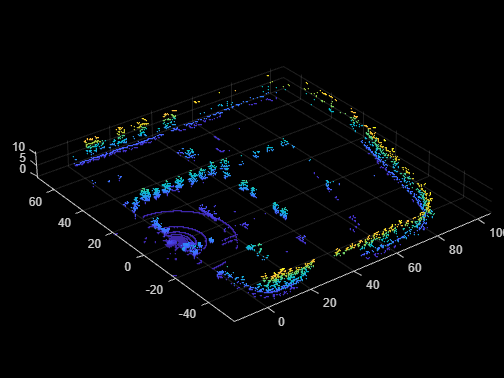

    detectionResults.Boxes{i} = box(:,[1,2,4,5,9]);
    detectionResults.Labels{i} = detectionResults.Labels{i}';
end

% Evaluate the object detector
metrics = evaluateObjectDetection(detectionResults,groundTruthData);
metrics.ClassMetrics

## Use on New Data

Once your detector is trained and tested, you can start using it to make predictions on unlabeled data. You can read in one image at a time and detect each object in that image:

ptCloud = pcread('testData/frame_0001.pcd');
[bboxes,scores,labels] = detect(detector,ptCloud);

bboxCar=bboxes(labels'=="car",:);
bboxCone=bboxes(labels'=="cone",:);
bboxBarrel=bboxes(labels'=="barrel",:);

Then visualize the detections:

figure
ax = pcshow(ptCloud.Location);
zoom(ax,1.5)
% currently this only shows one set of bboxes
showShape("cuboid",bboxCar,Color="green",Parent=ax,Opacity=0.3,LineWidth=1);
hold on;
showShape("cuboid",bboxCone,Color="red",Parent=ax,Opacity=0.3,LineWidth=1);
showShape("cuboid",bboxBarrel,Color="blue",Parent=ax,Opacity=0.3,LineWidth=6);
hold off;

Or, if you have a dataset of point clouds, you can create a datastore and make predictions on every point cloud. 

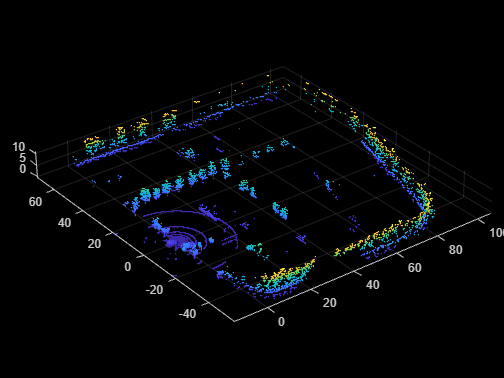

% Create a datastore of point clouds
location = fullfile(pwd, 'testData');
fds = fileDatastore(location,"ReadFcn",@pcread, 'FileExtensions', '.pcd');

% Create a point cloud viewer
player = pcplayer([xMin xMax],[yMin yMax],[zMin zMax]);


% Make and visualize detections
while isOpen(player) && hasdata(fds)
    ptCloud = read(fds);

    view(player,ptCloud);
    ax = player.Axes;

    [bboxes,scores,labels] = detect(detector,ptCloud,"Threshold",0.4);

    bboxCar=bboxes(labels'=="car",:);
    bboxCone=bboxes(labels'=="cone",:);
    bboxBarrel=bboxes(labels'=="barrel",:);
    showShape("cuboid",bboxCar,Color="green",Parent=ax,Opacity=0.3,LineWidth=1);
    hold on;
    showShape("cuboid",bboxCone,Color="red",Parent=ax,Opacity=0.3,LineWidth=1);
    showShape("cuboid",bboxBarrel,Color="blue",Parent=ax,Opacity=0.3,LineWidth=1);
end 